Import the images taken inside a variable

%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090903001.jpg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/prueba.jpeg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090903008.jpg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/Prueba4.jpeg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/Libro1.jpeg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/Prueba5.jpeg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/Prueba6.jpeg");
%I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090902018.jpg");
I = imread("/Users/fcuervo/MATLAB-Drive/VisionArtificial/ProjectImages/P090831011.jpg");

Apply first layer of filters

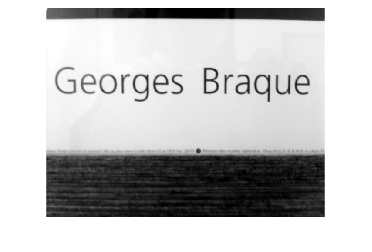

% Apply im2gray to convert an RGB image to grayscale.
gs = im2gray(I);
% Apply imadjust to increase the contrast of the image.
gsAdj = imadjust(gs);
% Show image after two filters
imshow(gsAdj)

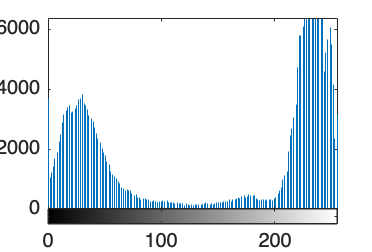

% Print histogram which shows us in a hisogram the gray scale, this scale allows us to identify in which range black or white colors are found.
imhist(gsAdj)

Implement a binarization method to separate black and white colors.

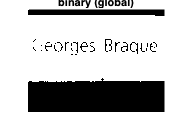

% Create a binary image by replacing all values determined threshold with 1s and setting all other values to 0s.
BW = imbinarize(gsAdj);
imshow(BW)
title("binary (global)")

Clean up some existing noise in the image

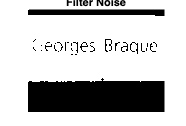

% Prepare parameter to apply, in this case it is an average filter to create an average.
H = fspecial("average",3);
% Here we apply an input array values outside the bounds of the array are assumed to equal the nearest array border value.
BWsmooth = imfilter(BW, H, "replicate");
imshow(BWsmooth)
title("Filter Noise")

Apply new binarization using parameters

% Perform a conversion of the previous image to be able to apply the last filter
img = im2uint8(BWsmooth)

img = 480×640 uint8 matrix
   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   255   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   255   255   255     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   255   255   255     0     0     0     0     0     0     0     0    

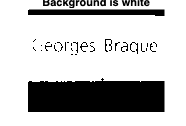

% This binarization works in the event that in our region of interest the background is white. The 'sensitivity' 
% parameter is applied since there may be regions with shadows, this parameter is responsible for cleaning up a bit around the text.
BWadapt = imbinarize(img, "adaptive", "ForegroundPolarity","dark",'Sensitivity',0.4);
imshow(BWadapt)
title("Background is white")


%imwrite(BWadapt, "/Users/fcuervo/MATLAB-Drive/VisionArtificial/PreprocessedImages/PrepocessedFinal3.jpg");
